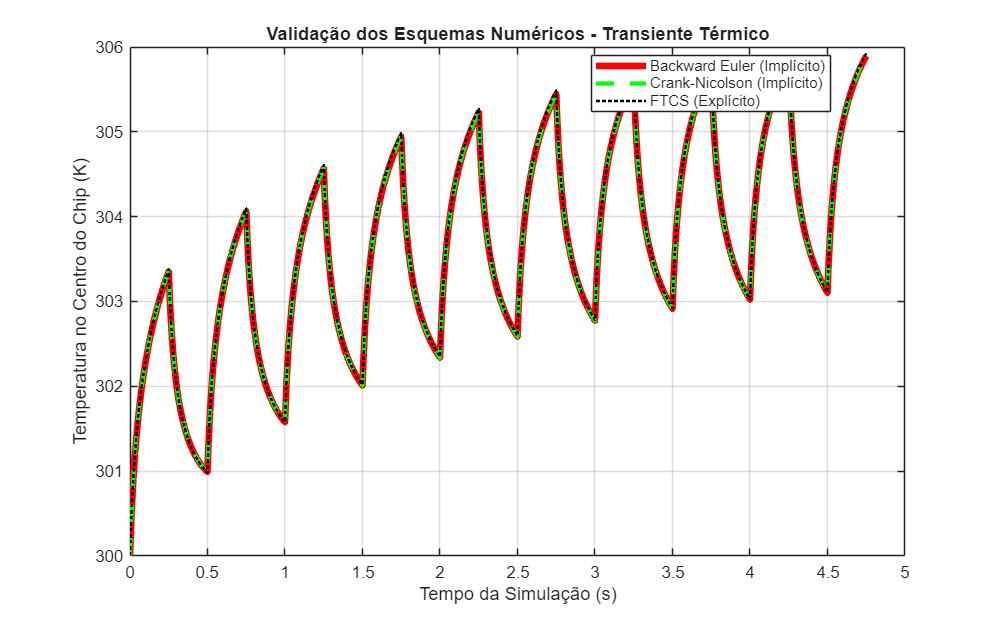

clear; clc; close all;

dados_ftcs = load('serie_tempo_ftcs.dat');
dados_be   = load('serie_tempo_btcs.dat');
dados_cn   = load('serie_tempo_cn.dat');

t_ftcs = dados_ftcs(:, 1);   T_centro_ftcs = dados_ftcs(:, 2);
t_be   = dados_be(:, 1);     T_centro_be   = dados_be(:, 2);
t_cn   = dados_cn(:, 1);     T_centro_cn   = dados_cn(:, 2);

figure('Name', 'Comparacao dos Metodos Numéricos', 'Position', [100, 100, 800, 500]);

plot(t_be, T_centro_be, 'r-', 'LineWidth', 4); hold on;       
plot(t_cn, T_centro_cn, 'g--', 'LineWidth', 2.5); hold on;    
plot(t_ftcs, T_centro_ftcs, 'k:', 'LineWidth', 1.5);        

title('Validação dos Esquemas Numéricos - Transiente Térmico');
xlabel('Tempo da Simulação (s)');
ylabel('Temperatura no Centro do Chip (K)');
legend('Backward Euler (Implícito)', 'Crank-Nicolson (Implícito)', 'FTCS (Explícito)', 'Location', 'best');
grid on;